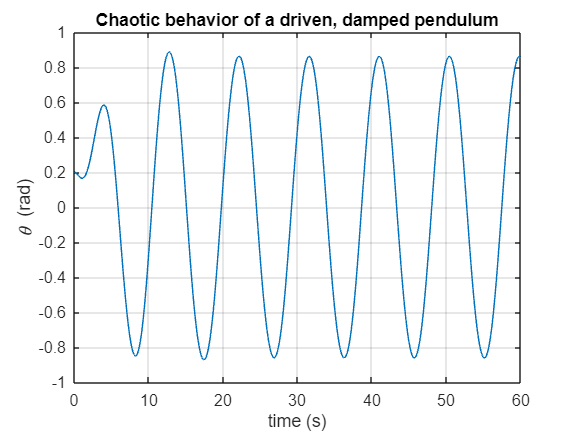

% Constants
g = 9.8;           % acceleration due to gravity (m/s^2)
l = 9.8;           % length of pendulum (m)
q = 0.5;           % damping coefficient
Fd = 0.5;          % driving force amplitude
OmegaD = 2/3;      % driving frequency
delta_t = 0.04;    % time step size

% Initial conditions
theta0 = 0.2;
omega0 = 0;

% Time span
t_final = 60;
t = 0:delta_t:t_final;
N = length(t);

% Initialization
theta = zeros(1, N);
omega = zeros(1, N);
theta(1) = theta0;
omega(1) = omega0;

% Euler-Cromer method
for i=1:N-1
    omega(i+1) = omega(i) - (g/l)*sin(theta(i))*delta_t - q*omega(i)*delta_t + Fd*sin(OmegaD*t(i))*delta_t;
    theta(i+1) = theta(i) + omega(i+1)*delta_t;
    
    % Keep theta within -pi to pi for plotting purposes
    if theta(i+1) > pi
        theta(i+1) = theta(i+1) - 2*pi;
    elseif theta(i+1) < -pi
        theta(i+1) = theta(i+1) + 2*pi;
    end
end

% Plot theta vs time
figure;
plot(t, theta);
xlabel('time (s)');
ylabel('\theta (rad)');
title('Chaotic behavior of a driven, damped pendulum');
grid on;